## Ploting Parameters

linewidth  = 2;
fontname   = 'TImes New Roman';
fontsize   = 20;
markersize = 10;

M = 64;
K = 18;
L = 13;

R = 200;
r = sqrt(3)/2*R;

theta_mid  = 0;
theta_step = pi/180;
theta_0    = theta_mid - theta_step/2;


$$r_{12} = \frac{ | \mathbf{h}_{1}^{\mathrm{H}} \mathbf{h}_{2} | }{ \Vert \mathbf{h}_{1} \Vert_{2} \Vert \mathbf{h}_{2} \Vert_{2} }$$



$$r_{12} = \frac{1}{M} \left | \mathrm{e}^{ -\mathrm{j}(\phi_{1} - \phi_{2})} \left [ \frac{1 - \mathrm{e}^{\mathrm{j}M\pi (\sin\theta_{1} - \sin\theta_{2})}}{1 - \mathrm{e}^{\mathrm{j}\pi (\sin\theta_{1} - \sin\theta_{2})}} \right]  \right|$$



$$r_{12} = \frac{1}{M} \left | \frac{\mathrm{e}^{\mathrm{j} M \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})}}{\mathrm{e}^{\mathrm{j}\frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})}} \left [ \frac{\mathrm{e}^{\mathrm{j} M \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})} - \mathrm{e}^{-\mathrm{j} M \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})}}{\mathrm{e}^{\mathrm{j}\frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})} - \mathrm{e}^{-\mathrm{j}\frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})}} \right]  \right|$$



$$r_{12} = \frac{1}{M} \left | \frac{\sin \left( M \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2}) \right) }{\sin \left( \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2}) \right)} \right|$$


r_12 = @(theta_1,theta_2) abs(sin(M*pi/2*(sin(theta_1) - sin(theta_2) + eps))./sin(pi/2*(sin(theta_1) - sin(theta_2) + eps)))/M;

theta_corr_range_1 = -pi:pi/180:pi;
theta_corr_range_2 = -pi/12:pi/1800:pi/12;
theta_corr_range_3 = pi/4 + (-pi/12:pi/1800:pi/12);
theta_corr_range_4 = pi/2 + (-pi/9:pi/1800:pi/9);

z_range_1 = ones(1,length(theta_corr_range_1));
z_range_2 = ones(1,length(theta_corr_range_2));
z_range_3 = ones(1,length(theta_corr_range_3));
z_range_4 = ones(1,length(theta_corr_range_4));

[T_range_11,T_range_12] = meshgrid(theta_corr_range_1,theta_corr_range_1);
[T_range_21,T_range_22] = meshgrid(theta_corr_range_2,theta_corr_range_2);
[T_range_31,T_range_32] = meshgrid(theta_corr_range_3,theta_corr_range_3);
[T_range_41,T_range_42] = meshgrid(theta_corr_range_4,theta_corr_range_4);

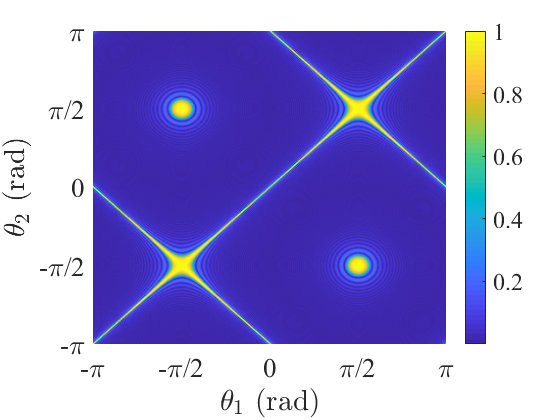

surf(T_range_11,T_range_12,r_12(T_range_11,T_range_12),'edgecolor','none');
view(2);

xlabel('$\theta_{1}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$\theta_{2}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
zlabel('Correlation coefficient','fontname',fontname,'fontsize',fontsize);

xticks([-pi -pi/2 0 pi/2 pi]);
xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});

yticks([-pi -pi/2 0 pi/2 pi]);
yticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});

xlim([-pi, pi]);
ylim([-pi, pi]);
zlim([0 1]);

set(gca,'fontname',fontname,'fontsize',fontsize);
colorbar;

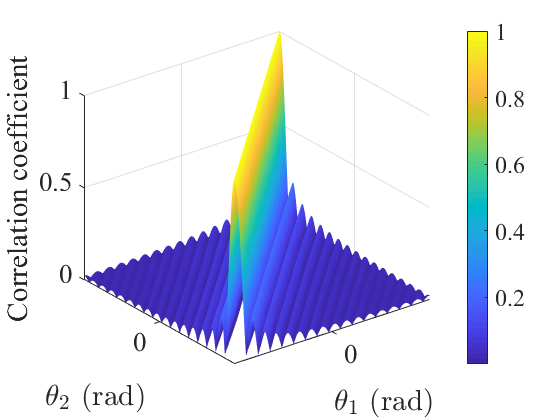

surf(T_range_21,T_range_22,r_12(T_range_21,T_range_22),'edgecolor','none');

xlabel('$\theta_{1}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$\theta_{2}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
zlabel('Correlation coefficient','fontname',fontname,'fontsize',fontsize);

xticks(0);
xticklabels('0');

yticks(0);
yticklabels('0');

xlim([-pi/12, pi/12]);
ylim([-pi/12, pi/12]);
zlim([0 1]);

set(gca,'fontname',fontname,'fontsize',fontsize);
colorbar;

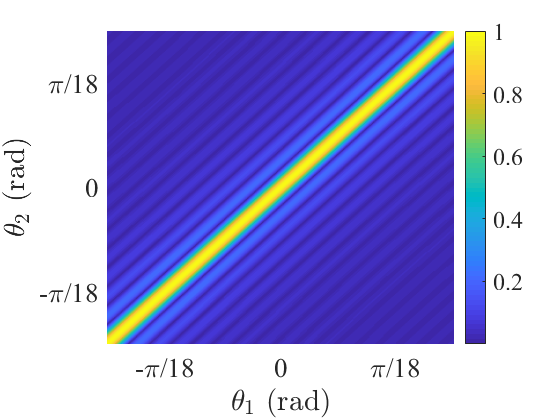

surf(T_range_21,T_range_22,r_12(T_range_21,T_range_22),'edgecolor','none');
view(2);

xlabel('$\theta_{1}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$\theta_{2}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
zlabel('Correlation coefficient','fontname',fontname,'fontsize',fontsize);

xticks([-pi/18 0 pi/18]);
xticklabels({'-\pi/18','0','\pi/18'});

yticks([-pi/18 0 pi/18]);
yticklabels({'-\pi/18','0','\pi/18'});

xlim([-pi/12, pi/12]);
ylim([-pi/12, pi/12]);
zlim([0 1]);

set(gca,'fontname',fontname,'fontsize',fontsize);
colorbar;

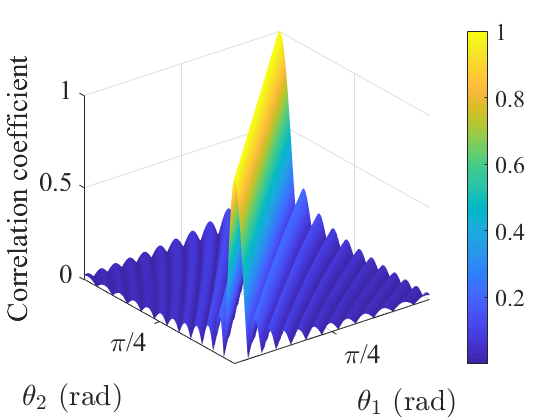

surf(T_range_31,T_range_32,r_12(T_range_31,T_range_32),'edgecolor','none');

xlabel('$\theta_{1}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$\theta_{2}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
zlabel('Correlation coefficient','fontname',fontname,'fontsize',fontsize);

xticks(pi/4);
xticklabels('\pi/4');

yticks(pi/4);
yticklabels('\pi/4');

xlim([pi/4-pi/12, pi/4+pi/12]);
ylim([pi/4-pi/12, pi/4+pi/12]);
zlim([0 1]);

set(gca,'fontname',fontname,'fontsize',fontsize);
colorbar;

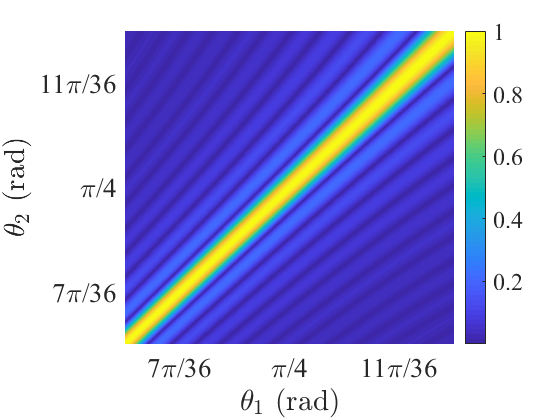

surf(T_range_31,T_range_32,r_12(T_range_31,T_range_32),'edgecolor','none');
view(2);

xlabel('$\theta_{1}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$\theta_{2}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
zlabel('Correlation coefficient','fontname',fontname,'fontsize',fontsize);

xticks([pi/4-pi/18 pi/4 pi/4+pi/18]);
xticklabels({'7\pi/36','\pi/4','11\pi/36'});

yticks([pi/4-pi/18 pi/4 pi/4+pi/18]);
yticklabels({'7\pi/36','\pi/4','11\pi/36'});

xlim([pi/4-pi/12, pi/4+pi/12]);
ylim([pi/4-pi/12, pi/4+pi/12]);
zlim([0 1]);

set(gca,'fontname',fontname,'fontsize',fontsize);
colorbar;

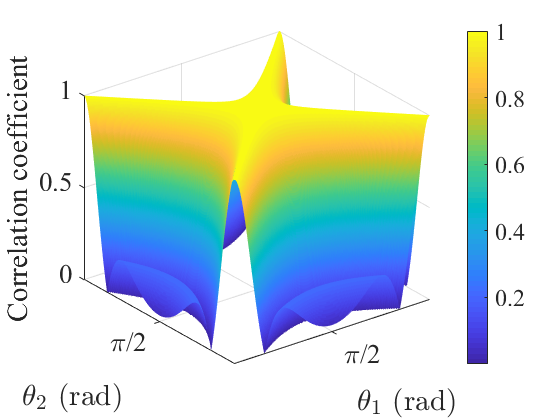

surf(T_range_41,T_range_42,r_12(T_range_41,T_range_42),'edgecolor','none');

xlabel('$\theta_{1}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$\theta_{2}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
zlabel('Correlation coefficient','fontname',fontname,'fontsize',fontsize);

xticks(pi/2);
xticklabels('\pi/2');

yticks(pi/2);
yticklabels('\pi/2');

xlim([pi/2-pi/9, pi/2+pi/9]);
ylim([pi/2-pi/9, pi/2+pi/9]);
zlim([0 1]);

set(gca,'fontname',fontname,'fontsize',fontsize);
colorbar;

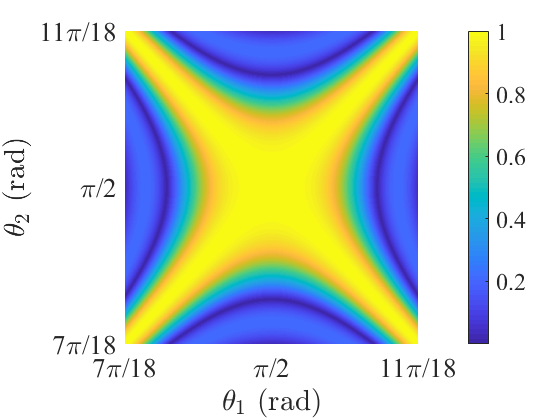

surf(T_range_41,T_range_42,r_12(T_range_41,T_range_42),'edgecolor','none');
view(2);

xlabel('$\theta_{1}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$\theta_{2}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
zlabel('Correlation coefficient','fontname',fontname,'fontsize',fontsize);

xticks([7*pi/18 pi/2 11*pi/18]);
xticklabels({'7\pi/18','\pi/2','11\pi/18'});

yticks([7*pi/18 pi/2 11*pi/18]);
yticklabels({'7\pi/18','\pi/2','11\pi/18'});

xlim([pi/2-pi/9, pi/2+pi/9]);
ylim([pi/2-pi/9, pi/2+pi/9]);
zlim([0 1]);

set(gca,'fontname',fontname,'fontsize',fontsize);
colorbar;

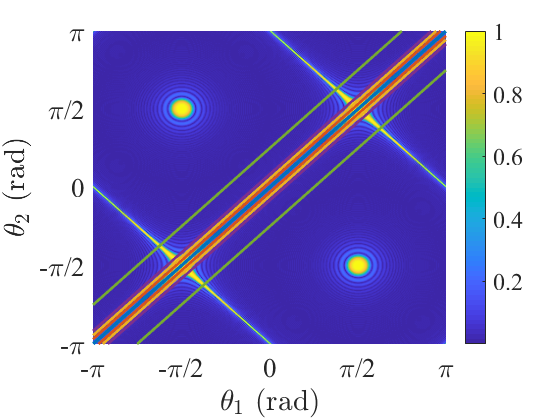

surf(T_range_11,T_range_12,r_12(T_range_11,T_range_12),'edgecolor','none');
view(2);
hold on;
plot3(theta_corr_range_1,theta_corr_range_1 + pi/320,z_range_1,'color',[0 0.4470 0.7410]     ,'linewidth',linewidth);
plot3(theta_corr_range_1,theta_corr_range_1 - pi/320,z_range_1,'color',[0 0.4470 0.7410]     ,'linewidth',linewidth);
plot3(theta_corr_range_1,theta_corr_range_1 + pi/32 ,z_range_1,'color',[0.8500 0.3250 0.0980],'linewidth',linewidth);
plot3(theta_corr_range_1,theta_corr_range_1 - pi/32 ,z_range_1,'color',[0.8500 0.3250 0.0980],'linewidth',linewidth);
plot3(theta_corr_range_1,theta_corr_range_1 + pi/18 ,z_range_1,'color',[0.9290 0.6940 0.1250],'linewidth',linewidth);
plot3(theta_corr_range_1,theta_corr_range_1 - pi/18 ,z_range_1,'color',[0.9290 0.6940 0.1250],'linewidth',linewidth);
plot3(theta_corr_range_1,theta_corr_range_1 + pi/12 ,z_range_1,'color',[0.4940 0.1840 0.5560],'linewidth',linewidth);
plot3(theta_corr_range_1,theta_corr_range_1 - pi/12 ,z_range_1,'color',[0.4940 0.1840 0.5560],'linewidth',linewidth);
plot3(theta_corr_range_1,theta_corr_range_1 + pi/4  ,z_range_1,'color',[0.4660 0.6740 0.1880],'linewidth',linewidth);
plot3(theta_corr_range_1,theta_corr_range_1 - pi/4  ,z_range_1,'color',[0.4660 0.6740 0.1880],'linewidth',linewidth);
hold off;

xlabel('$\theta_{1}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$\theta_{2}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
zlabel('Correlation coefficient','fontname',fontname,'fontsize',fontsize);

xticks([-pi -pi/2 0 pi/2 pi]);
xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});

yticks([-pi -pi/2 0 pi/2 pi]);
yticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});

xlim([-pi, pi]);
ylim([-pi, pi]);
zlim([0 1]);

set(gca,'fontname',fontname,'fontsize',fontsize);
colorbar;

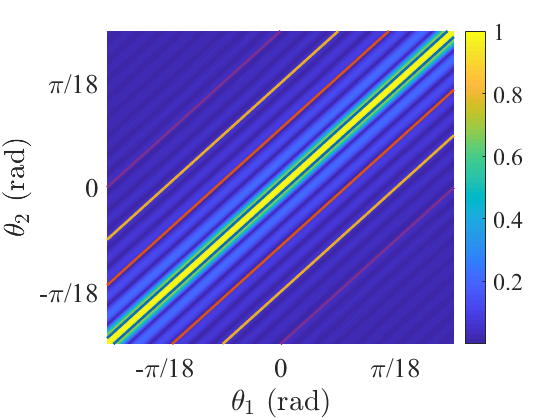

surf(T_range_21,T_range_22,r_12(T_range_21,T_range_22),'edgecolor','none');
view(2);
hold on;
plot3(theta_corr_range_2,theta_corr_range_2 + pi/320,z_range_2,'color',[0 0.4470 0.7410]     ,'linewidth',linewidth);
plot3(theta_corr_range_2,theta_corr_range_2 - pi/320,z_range_2,'color',[0 0.4470 0.7410]     ,'linewidth',linewidth);
plot3(theta_corr_range_2,theta_corr_range_2 + pi/32 ,z_range_2,'color',[0.8500 0.3250 0.0980],'linewidth',linewidth);
plot3(theta_corr_range_2,theta_corr_range_2 - pi/32 ,z_range_2,'color',[0.8500 0.3250 0.0980],'linewidth',linewidth);
plot3(theta_corr_range_2,theta_corr_range_2 + pi/18 ,z_range_2,'color',[0.9290 0.6940 0.1250],'linewidth',linewidth);
plot3(theta_corr_range_2,theta_corr_range_2 - pi/18 ,z_range_2,'color',[0.9290 0.6940 0.1250],'linewidth',linewidth);
plot3(theta_corr_range_2,theta_corr_range_2 + pi/12 ,z_range_2,'color',[0.4940 0.1840 0.5560],'linewidth',linewidth);
plot3(theta_corr_range_2,theta_corr_range_2 - pi/12 ,z_range_2,'color',[0.4940 0.1840 0.5560],'linewidth',linewidth);
hold off;

xlabel('$\theta_{1}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$\theta_{2}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
zlabel('Correlation coefficient','fontname',fontname,'fontsize',fontsize);

xticks([-pi/18 0 pi/18]);
xticklabels({'-\pi/18','0','\pi/18'});

yticks([-pi/18 0 pi/18]);
yticklabels({'-\pi/18','0','\pi/18'});

xlim([-pi/12, pi/12]);
ylim([-pi/12, pi/12]);
zlim([0 1]);

set(gca,'fontname',fontname,'fontsize',fontsize);
colorbar;

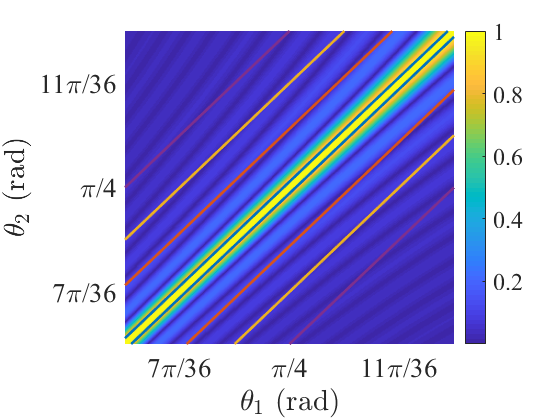

surf(T_range_31,T_range_32,r_12(T_range_31,T_range_32),'edgecolor','none');
view(2);
hold on;
plot3(theta_corr_range_3,theta_corr_range_3 + pi/320,z_range_3,'color',[0 0.4470 0.7410]     ,'linewidth',linewidth);
plot3(theta_corr_range_3,theta_corr_range_3 - pi/320,z_range_3,'color',[0 0.4470 0.7410]     ,'linewidth',linewidth);
plot3(theta_corr_range_3,theta_corr_range_3 + pi/32 ,z_range_3,'color',[0.8500 0.3250 0.0980],'linewidth',linewidth);
plot3(theta_corr_range_3,theta_corr_range_3 - pi/32 ,z_range_3,'color',[0.8500 0.3250 0.0980],'linewidth',linewidth);
plot3(theta_corr_range_3,theta_corr_range_3 + pi/18 ,z_range_3,'color',[0.9290 0.6940 0.1250],'linewidth',linewidth);
plot3(theta_corr_range_3,theta_corr_range_3 - pi/18 ,z_range_3,'color',[0.9290 0.6940 0.1250],'linewidth',linewidth);
plot3(theta_corr_range_3,theta_corr_range_3 + pi/12 ,z_range_3,'color',[0.4940 0.1840 0.5560],'linewidth',linewidth);
plot3(theta_corr_range_3,theta_corr_range_3 - pi/12 ,z_range_3,'color',[0.4940 0.1840 0.5560],'linewidth',linewidth);
plot3(theta_corr_range_3,theta_corr_range_3 + pi/4  ,z_range_3,'color',[0.4660 0.6740 0.1880],'linewidth',linewidth);
plot3(theta_corr_range_3,theta_corr_range_3 - pi/4  ,z_range_3,'color',[0.4660 0.6740 0.1880],'linewidth',linewidth);
hold off;

xlabel('$\theta_{1}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$\theta_{2}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
zlabel('Correlation coefficient','fontname',fontname,'fontsize',fontsize);

xticks([pi/4-pi/18 pi/4 pi/4+pi/18]);
xticklabels({'7\pi/36','\pi/4','11\pi/36'});

yticks([pi/4-pi/18 pi/4 pi/4+pi/18]);
yticklabels({'7\pi/36','\pi/4','11\pi/36'});

xlim([pi/4-pi/12, pi/4+pi/12]);
ylim([pi/4-pi/12, pi/4+pi/12]);
zlim([0 1]);

set(gca,'fontname',fontname,'fontsize',fontsize);
colorbar;

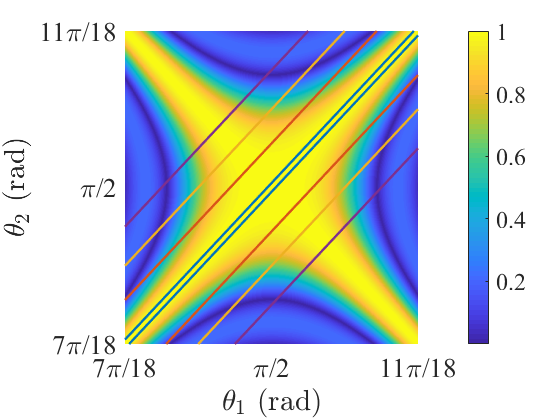

surf(T_range_41,T_range_42,r_12(T_range_41,T_range_42),'edgecolor','none');
view(2);
hold on;
plot3(theta_corr_range_4,theta_corr_range_4 + pi/320,z_range_4,'color',[0 0.4470 0.7410]     ,'linewidth',linewidth);
plot3(theta_corr_range_4,theta_corr_range_4 - pi/320,z_range_4,'color',[0 0.4470 0.7410]     ,'linewidth',linewidth);
plot3(theta_corr_range_4,theta_corr_range_4 + pi/32 ,z_range_4,'color',[0.8500 0.3250 0.0980],'linewidth',linewidth);
plot3(theta_corr_range_4,theta_corr_range_4 - pi/32 ,z_range_4,'color',[0.8500 0.3250 0.0980],'linewidth',linewidth);
plot3(theta_corr_range_4,theta_corr_range_4 + pi/18 ,z_range_4,'color',[0.9290 0.6940 0.1250],'linewidth',linewidth);
plot3(theta_corr_range_4,theta_corr_range_4 - pi/18 ,z_range_4,'color',[0.9290 0.6940 0.1250],'linewidth',linewidth);
plot3(theta_corr_range_4,theta_corr_range_4 + pi/12 ,z_range_4,'color',[0.4940 0.1840 0.5560],'linewidth',linewidth);
plot3(theta_corr_range_4,theta_corr_range_4 - pi/12 ,z_range_4,'color',[0.4940 0.1840 0.5560],'linewidth',linewidth);
plot3(theta_corr_range_4,theta_corr_range_4 + pi/4  ,z_range_4,'color',[0.4660 0.6740 0.1880],'linewidth',linewidth);
plot3(theta_corr_range_4,theta_corr_range_4 - pi/4  ,z_range_4,'color',[0.4660 0.6740 0.1880],'linewidth',linewidth);
hold off;

xlabel('$\theta_{1}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$\theta_{2}$ (rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
zlabel('Correlation coefficient','fontname',fontname,'fontsize',fontsize);

xticks([7*pi/18 pi/2 11*pi/18]);
xticklabels({'7\pi/18','\pi/2','11\pi/18'});

yticks([7*pi/18 pi/2 11*pi/18]);
yticklabels({'7\pi/18','\pi/2','11\pi/18'});

xlim([pi/2-pi/9, pi/2+pi/9]);
ylim([pi/2-pi/9, pi/2+pi/9]);
zlim([0 1]);

set(gca,'fontname',fontname,'fontsize',fontsize);
colorbar;

x_cell = [R R/2 -R/2 -R -R/2 R/2 R]';                                % Cell's x-coordinates
y_cell = [0 r    r    0 -r  -r   0]';                                % Cell's y-coordinates

radius = r*sqrt(rand(K,1));
theta  = theta_0 +  theta_step*rand(K,1);

x = radius.*cos(theta);
y = radius.*sin(theta);

N_CIRCLE_POINTS = 100;

theta_spread = theta_0 + theta_step*linspace(0,1,N_CIRCLE_POINTS);

x_spread = r*cos(theta_spread);
y_spread = r*sin(theta_spread);

% root_save = '../../../Google Drive/UFRJ/PhD/Codes/user-scheduling-massive-mimo/Figures/Cell/';
% 
% theta_beam = -pi:pi/1800:pi;
% 
% i = 1;
% 
% for theta_shift = -pi/2:pi/180:pi/2
%     
%     [x_theta_beam,y_theta_beam] = pol2cart(theta_beam,r*r_12(theta_beam,theta_shift));
%     
%     plot(x_cell,y_cell,'linewidth',linewidth);
%     hold on;
%     plot(x_theta_beam,y_theta_beam,'linewidth',linewidth);
%     hold off;
%     
%     title(['$\theta_{\mathrm{s}} = ' num2str(180*theta_shift/pi) '^{\circ}$'],'fontname',fontname,'fontsize',fontsize,'interpreter','latex');
%     xlabel('$x$ (in m)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
%     ylabel('$y$ (in m)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
%     
%     xlim([-1.25*R 1.25*R]);
%     ylim([-1.25*R 1.25*R]);
%     
%     set(gca,'fontname',fontname,'fontsize',fontsize);
%     
%     saveas(gcf,[root_save 'beampattern_' num2str(i)],'png');
%     
%     i = i + 1;
% end

## Distribution of the Users in a Small Piece of the Cell

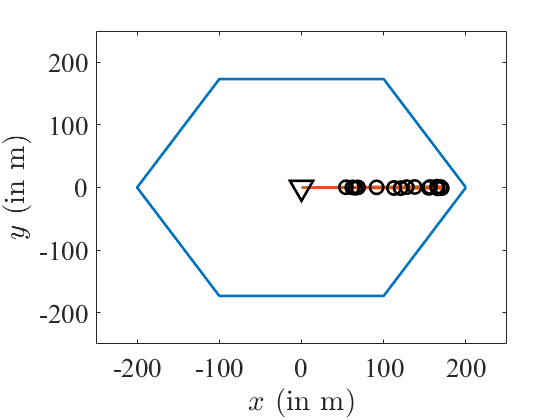

plot(x_cell,y_cell,'linewidth',linewidth);
hold on;
plot([0 x_spread 0],[0 y_spread 0],'linewidth',linewidth);
plot(0,0,'vk','linewidth',linewidth,'markersize',1.5*markersize);
plot(x,y,'ok','linewidth',linewidth,'markersize',markersize);

xlabel('$x$ (in m)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$y$ (in m)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

xlim([-1.25*R 1.25*R]);
ylim([-1.25*R 1.25*R]);

set(gca,'fontname',fontname,'fontsize',fontsize);